# Proper Orthogonal Decomposition 

## Aldo Schioppa, ISAE_SUPAERO, Toulouse

The following script's outcomes comprise the resulting modes of a quasi-stationary set of fluid-dynamics data (so-known **snapshots**) by employing the spod.m and pod.m functions. Besides, the user shall need to pass several inputs onto the script to automatically evaluate the time step, which is paramount to calculating the Nyquist frequency, sufficient and necessary to reconstruct discrete temporal signals.

The first section of the code comprises several constant with regard to the mesh size, time step and viscosity model.

close all; clc; clear variables; 

% Reference temperature.
T_0=273.15; %K
% Initial global cell size.
dx=0.5; %m
% Min cell size across the domain.
min_dx=0.00125; %\m
% Target CFL for the finest grid.
Cfl=35;

Often times, rather than varying the mesh refinement, it is preferable to reduce the time step for numerical schemes' stability. The same lever of action has a beneficial effect on detecting the dominant frequency of the flow, despite of increasing the computational time. All things considered, the target CFL acts as a time-step regulator. The variables ***dx ***and ***min_dx ***are grid's intrinsic parameters.

## **Inputs **

Please consult [1] (Appendix A) for further information concerning the initialisation of a viscous compressible flows. 

% Reference length
c=1; %m
% Maximum airfoil thickness
delta=0.12*c;
% Freestream temperature
T_inf=275.15; %K
% Reynolds number 
Re=2000;
% Mach number
M=0.85;
% Ideal gas model
gamma=1.4;
R=287;
% Dominant Str
St=[1,0.07];

The varibale ***St ***represents a vector of expected non-dimensional dominant frequencies (Strouhal number) of the flow, possibly obtainable from consolidated work in literature. The Strouhal number is paramount to define the initial time step.

## Output 

Substantially, the first subsection represents the procedure to initialise a compressible viscous solution [1] (Appendix A). The second subdivision is a complete and simplisticly coded definition of the time step vector. 

% Domain length 
L=20*2*c; %m
% Freestream viscosity.
mu_inf=1.716e-05*(T_inf/T_0)*((T_0+110.4)/(T_inf+110.4)); %(m^2)/s
% Speed of sound.
a_inf=(gamma*R*T_inf)^0.5; %m/s
% Freestream velocity.
V_inf=M*a_inf; % m/s
% Freestream density. 
rho_inf=Re*mu_inf/(V_inf*c); %Kg/m^3
% Freestream pressure.
p_inf=rho_inf*R*T_inf; %Pa

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Time step %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 

% Convective time.
conv_dt=c/V_inf; %s
% Dominant frequency.
F=St*V_inf/c; %Hz
% Vector of dominant time step.
Dt=1./F; %s
Dt(end+1)=conv_dt;
% Division by 50 for first time step.
Dt=Dt/50; %s
% Most restrictive time step.
dt=min(Dt); %s
% Max CFL (for the finest mesh).
CFL=dt*(V_inf+a_inf)/min_dx;
% New dt after CFL correction.
dt=Cfl*min_dx/(V_inf+a_inf);
% Time step vector for time convergence. Progression of 1/5.
Dt=[dt,dt/5,dt/5/5]; %s

Hereby the definitions:

***conv_dt: ***Convective time associated to the geometry. The convective time is also a possible dominant time scale of the flow, reason for which it is here included.

***F: ***Vector of dominant frequencies from the Strouhal number ***St***.

***Dt: ***Vector of dominant time scales, to which the ***conv_dt*** is added in. Subsequently, the vector is scaled down by a factor of 50. The latter operation has 2 beneficial effects: 1) Conservativity over the **minimum** time step for retrieving the dominant frequencies. 2) It remarkably increases the frequency of acquisition with respect to the Nyquist frequency.

***dt: ***The minimum time step possible among the ones in ***Dt***, which results in the more restricitve scale. Therefore, each and every time scale shall be retrieved. The time step is adjusted through the maximum ***CFL ***(finest grid). Generally, it is required that the user set a CFL roughly equal to 35 over the geometry, so that the same drastically drop across the rest of the domain, particularily for the value retained in the wake region, where the CFL must be considerably low. 

## Data unpacking

To set the grid for plots matter and visualise the fluid-dynamic fields retained in the snapshot files.

It is recommended that the user check out on the data. In this case, the command window would display the variables' name (Star-CCM+) being exported through the table properties.

filename='D:\ResearchProject_Major\Data\Re2000\Snapshots_WAKE\WAKE_63251.csv';
d=readtable(filename,'PreserveVariableNames',true);
display(d.Properties.VariableNames);

  1×5 cell array

    {'Dt'}    {'Velocity[j] (m/s)'}    {'X (m)'}    {'Y (m)'}    {'Z (m)'}



Subsequently, define the indexes for the corresponding variables.

% idx_t=1; if existent
idx_F=2; % Defining the index for the field the user shall apply the POD to.

% Grid coordinates indexes.
idx_x=3;
idx_y=4;
idx_z=5; % Not noteworthy for 2D fields.

In this case, for instance, the **idx_F** points at the transversal velocity field.

% Coordinates extraction.
x=d.(idx_x)/c; % non-dimensionalisation with respect to the chord.
y=d.(idx_y)/c; 

% Grid generation.
[X,Y]=meshgrid(unique(x),unique(y));

% chord-wise and chord-transversal coordinates vectors.
x=linspace(min(x),max(x),size(X,1));
y=linspace(min(y),max(y),size(Y,2));

## Data extraction

This section permits looping over the snapshots files stored in a folder of which the path must be specified.

% Specify the folder where the files resire.
myFolder='D:\ResearchProject_Major\Data\Re2000\Snapshots_WAKE'; % To modify 
% Check to make sure that folder actually exists.  Warn user if it does not.
if ~isfolder(myFolder)
    errorMessage=sprintf(['Error: The following folder does not exist:\n%s\nPlease' ...
        'specify a new folder.'], myFolder);
    uiwait(warndlg(errorMessage));
    myFolder=uigetdir(); % Ask for a new one.
    if myFolder==0
         return;
    end
end

% Get a list of all files in the folder with the desired file name pattern.
filePattern=fullfile(myFolder, '*.csv'); % Change to whatever pattern the user needs.
theFiles=dir(filePattern);
disp('Reading the snaphots file might take a while...')

Reading the snaphots file might take a while...


for jj=1:length(theFiles) 
    % Access the file name.
    baseFileName=theFiles(jj).name;
    % Build the path.
    fullFileName=fullfile(theFiles(jj).folder, baseFileName);
    if rem(jj,2000)==0 % displying the status each 2000 snapshots.
    fprintf(1,'Now reading %s\n',fullFileName);
    disp('------------------------------------')
    end
    % Read data.
    data=readmatrix(fullFileName);
    % Crucial step is sorting data with respect to the grid coordinates.
    data=sortrows(data,[idx_x,idx_y,idx_z]);
    % Store sorted data vector in a cell array.
    Field{jj}=data(:,idx_F);
    % Finally, reshape according to the grid discretisation.
    field_Snapshots(jj,:,:)=reshape(Field{jj},size(X,1),[]);
end

Now reading D:\ResearchProject_Major\Data\Re2000\Snapshots_WAKE\WAKE_65250.csv


------------------------------------


Now reading D:\ResearchProject_Major\Data\Re2000\Snapshots_WAKE\WAKE_67250.csv


------------------------------------


Now reading D:\ResearchProject_Major\Data\Re2000\Snapshots_WAKE\WAKE_69250.csv


------------------------------------


Now reading D:\ResearchProject_Major\Data\Re2000\Snapshots_WAKE\WAKE_71250.csv


------------------------------------


Now reading D:\ResearchProject_Major\Data\Re2000\Snapshots_WAKE\WAKE_73250.csv


------------------------------------


Now reading D:\ResearchProject_Major\Data\Re2000\Snapshots_WAKE\WAKE_75250.csv


------------------------------------


Now reading D:\ResearchProject_Major\Data\Re2000\Snapshots_WAKE\WAKE_77250.csv


------------------------------------


% Time vector
t=(1:length(theFiles))*Dt(1);

## POD 

disp('It migth be take a while...');

It migth be take a while...


% POD
[U_POD, S_POD, V_POD] = pod(field_Snapshots,'econ');
% SPOD
OPT.mean='blockwise';
[L,P,f] = spod(field_Snapshots,[],[],[],Dt(1),OPT);

 
SPOD parameters
------------------------------------
Spectrum type             : one-sided (real-valued signal)
No. of snaphots per block : 1024
Block overlap             : 512
No. of blocks             : 26
Windowing fct. (time)     : Hamming
Weighting fct. (space)    : uniform
Mean                      : blockwise mean
 
Calculating temporal DFT
------------------------------------
block 1/26 (1:1024)
block 2/26 (513:1536)
block 3/26 (1025:2048)
block 4/26 (1537:2560)
block 5/26 (2049:3072)
block 6/26 (2561:3584)
block 7/26 (3073:4096)
block 8/26 (3585:4608)
block 9/26 (4097:5120)
block 10/26 (4609:5632)
block 11/26 (5121:6144)
block 12/26 (5633:6656)
block 13/26 (6145:7168)
block 14/26 (6657:7680)
block 15/26 (7169:8192)
block 16/26 (7681:8704)
block 17/26 (8193:9216)
block 18/26 (8705:9728)
block 19/26 (9217:10240)
block 20/26 (9729:10752)
block 21/26 (10241:11264)
block 22/26 (10753:11776)
block 23/26 (11265:12288)
block 24/26 (11777:12800)
block 25/26 (12289:13312)
block 26/26 

The temporal mean of each block is re-allocated into the zero-frequency bin when the function takes the Fourier transform, thus the mean has already been removed from the non-zero frequency components and there is no need to subtract it. However, the user might want to set **OPTS.mean='blockwise'** to remove the mean of each block if your data has a long-time trend that leaks into low frequencies (for example if your data is not utterly stationary).

## Plot - Modes energy VS rank

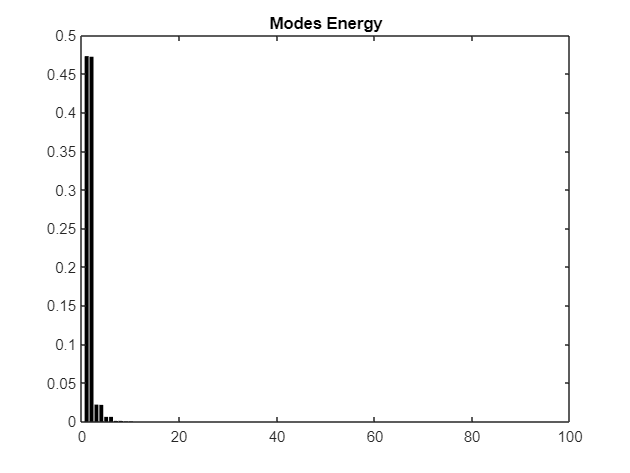

% The pod.m function outputs a diagonal matrix S_POD whose coefficients are
% the square root of the modes energy in descending order.
ModeEnergies=S_POD.^2;
% Normalisation w.r.t. the total energy.
ModeEnergyFraction=ModeEnergies/sum(ModeEnergies);
% Plot
figure('Color','w');
bar(1:length(ModeEnergies),ModeEnergyFraction,'k'); 
xlim([0 100]);
title('Modes Energy');

## Plot - Frequency spectrum

figure
loglog(f*c/V_inf,L); grid on; grid minor; 
xlab=xlabel("$St [-]$"); ylab=ylabel('\textbf{FFT of} pressure'); 
set(xlab,'Interpreter', 'latex','FontSize',16); 
set(ylab,'Interpreter','latex','Rotation',90,'FontSize',14); 
set(gca,'FontSize',11);

## Animate the first n snapshots using SPOD.m

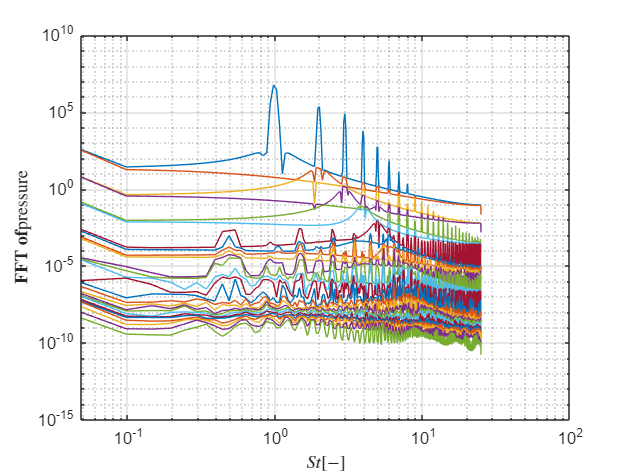

n=100; % Number of snapshost to visualise

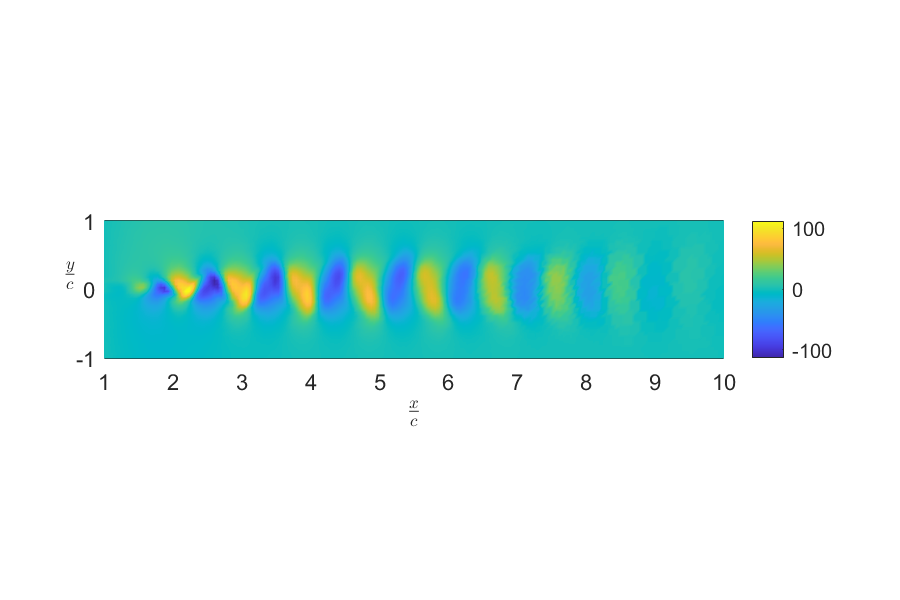

figure('Renderer','painters','Position',[10 10 600 400])
for ti=1:n
    pcolor(X,flip(Y),squeeze(field_Snapshots(ti,:,:))); colorbar
    axis tight equal; shading interp;
    xlab=xlabel("$\frac{x}{c}$"); ylab=ylabel("$\frac{y}{c}$"); 
    set(xlab,'Interpreter', 'latex','FontSize',20); 
    set(ylab,'Interpreter','latex','Rotation',0,'FontSize',20); 
    set(gca,'FontSize',11);
    pause(0.05)
    drawnow
end

## Visualize the SPOD modes at multiple frequencies

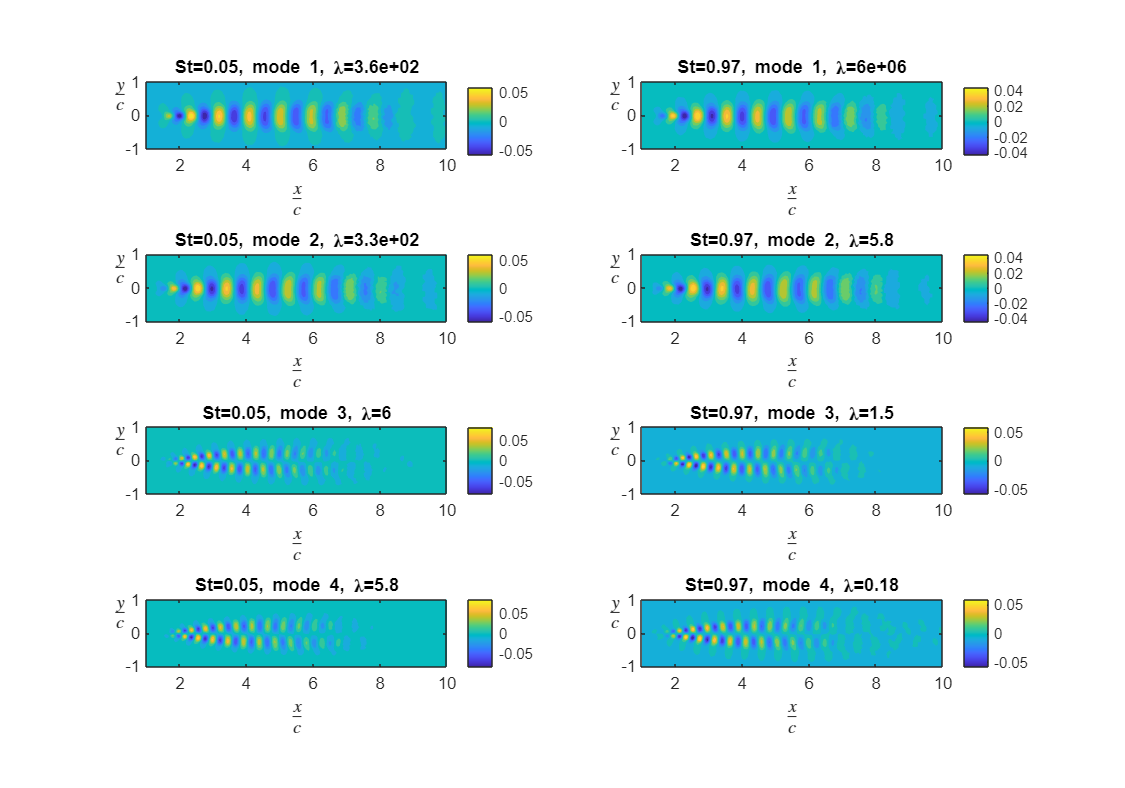

% P(fi,:,:,mi), the first index loops over the frequencies, while the last one
% is mode number ranked in descending order by modal energy. Lambda is
% the energy content associated to the mi-th modes at fi-th frequency.

figure('Renderer','painters','Position',[10 10 1000 700])
count=1;
n_f=2; % Number of frequencies.
n_m=4; % Number of modes.
for mi = [1 2 3 4] % modes counter. 
    for fi = [2 21] % frequencies counter.
        subplot(n_m,n_f,count)
        contourf(X,Y,real(squeeze(P(fi,:,:,mi))),11,'edgecolor','none'); axis equal tight; 
        caxis(max(abs(caxis))*[-1 1]); 
        shading interp; colorbar;
        xlab=xlabel("$\frac{x}{c}$"); ylab=ylabel("$\frac{y}{c}$"); 
        set(xlab,'Interpreter', 'latex','FontSize',20); 
        set(ylab,'Interpreter','latex','Rotation',0,'FontSize',20); 
        set(gca,'FontSize',11);
        title(['St=' num2str(f(fi)*c/V_inf,'%.2f') ', mode ' num2str(mi) ', ' ...
            '\lambda=' num2str(L(fi,mi),'%.2g')])
        xlim([min(x) max(x)]); ylim([min(y) max(y)])
        count=count+1;
    end
end

Note that the above 4 modes are wave pairs two by two. This is due to the POD nature, which is a real-valued function, thus meaning that, in order to produce a propagating wave, a pair of two phases-shifted modes are necessary.

## Animate the previous modes

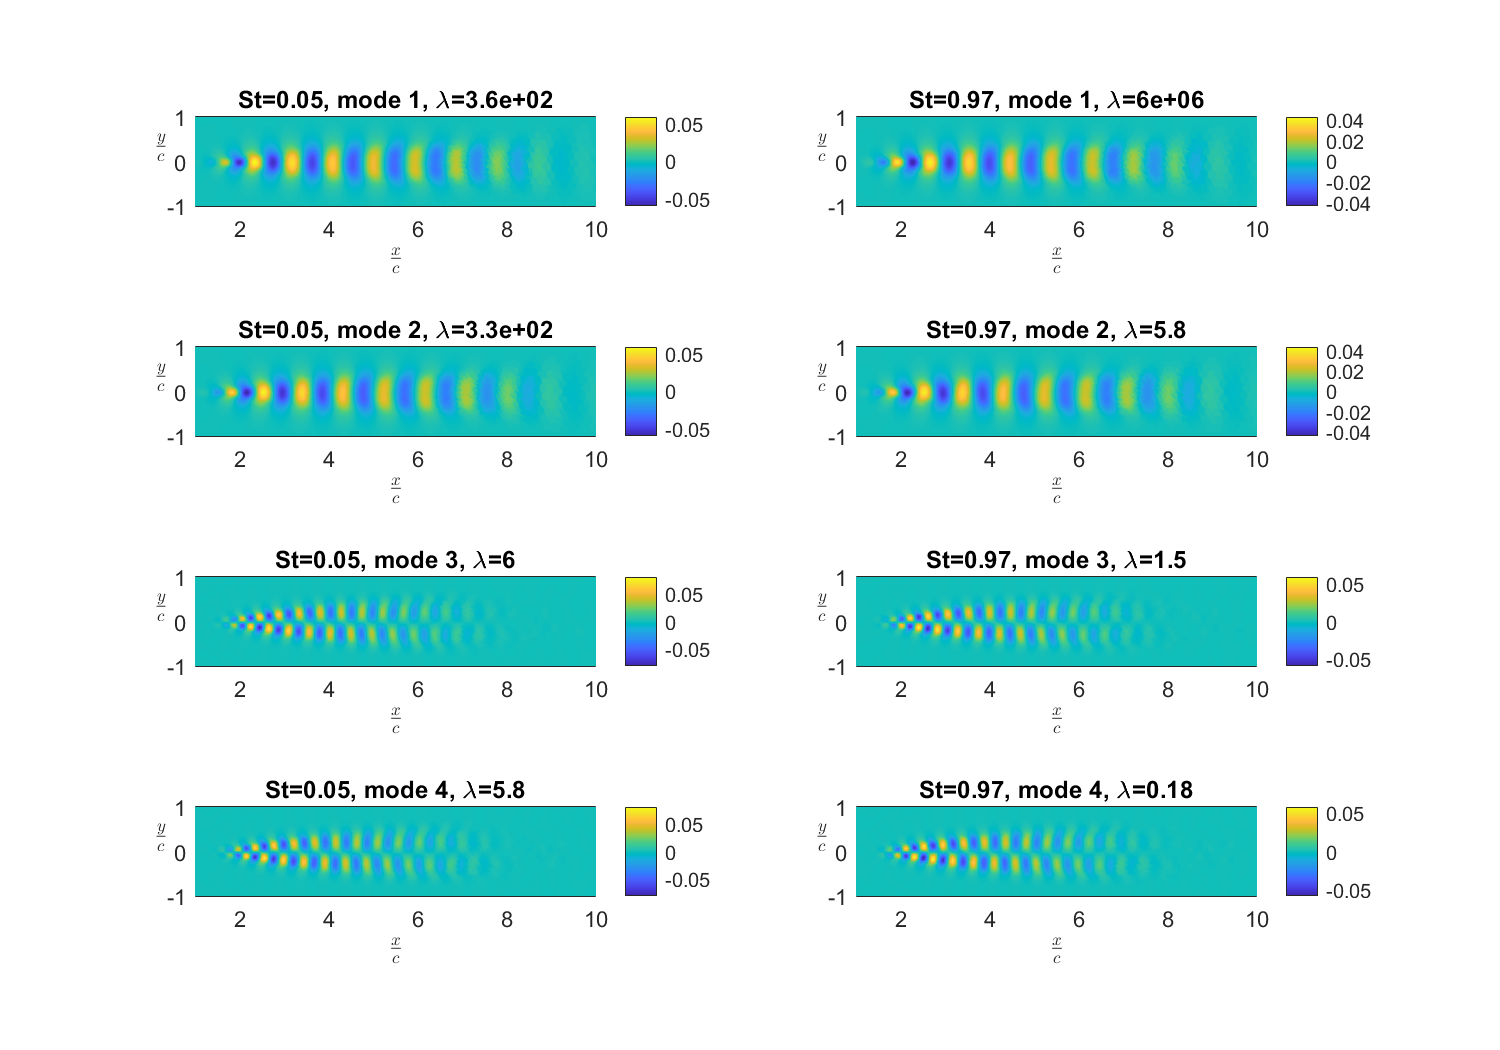

figure('Renderer','painters','Position',[10 10 1000 700])
nt=100;
T=1/f(2); % period 
time=linspace(0,T,nt); % animate over one period
count=1;
n_f=2;
n_m=4;
for ti=1:nt
    for mi=[1 2 3 4]
        for fi=[2 21]
            subplot(n_m,n_f,count)
            pcolor(X,Y,real(squeeze(P(fi,:,:,mi)*exp(2i*pi*f(fi)*time(ti))))); 
            shading interp; axis equal tight; 
            caxis(max(abs(caxis))*[-1 1]); colorbar
            xlab=xlabel("$\frac{x}{c}$"); ylab=ylabel("$\frac{y}{c}$"); 
            set(xlab,'Interpreter', 'latex','FontSize',20); 
            set(ylab,'Interpreter','latex','Rotation',0,'FontSize',20); 
            set(gca,'FontSize',11); 
            title(['St=' num2str(f(fi)*c/V_inf,'%.2f') ', mode ' num2str(mi) ', ' ...
                '\lambda=' num2str(L(fi,mi),'%.2g')]);
            xlim([min(x) max(x)]); ylim([min(y) max(y)])
            count=count+1;
            hold on
        end
    end
    drawnow
    hold off
    count=1;
end

Note how all wavepackets travel at approximately the same phase speed. The reason is that their streamwise wavenumber changes with frequency such that the speed is approximately constant.

## Plots the m-th mode with pod.m for comparison purposes

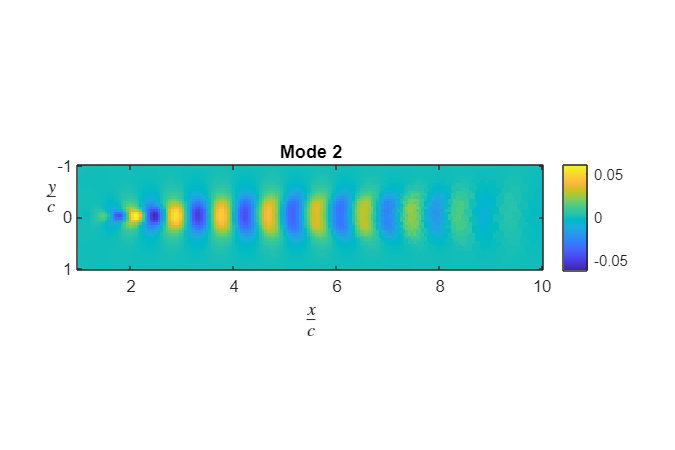

m=2; % mode index
figure('Renderer','painters','Position',[10 10 600 400])
modeShape=real(squeeze(U_POD(m,:,:))); 
imagesc(x,y,modeShape); axis equal tight; shading interp;
caxis([-max(abs(modeShape(:))) max(abs(modeShape(:)))]); 
colormap; colorbar
xlab=xlabel("$\frac{x}{c}$"); ylab=ylabel("$\frac{y}{c}$"); 
set(xlab,'Interpreter', 'latex','FontSize',20); 
set(ylab,'Interpreter','latex','Rotation',0,'FontSize',20); 
set(gca,'FontSize',11);
title(['Mode ' num2str(m,'%0.0f')]);

## Plots the time coefficient matrix (temporal expansion) V for modes m or more

The output matrix V_POD is a matrix whose rows are the modes expansion coefficient. Therefore it is possible to plot the expansion coefficient in time.

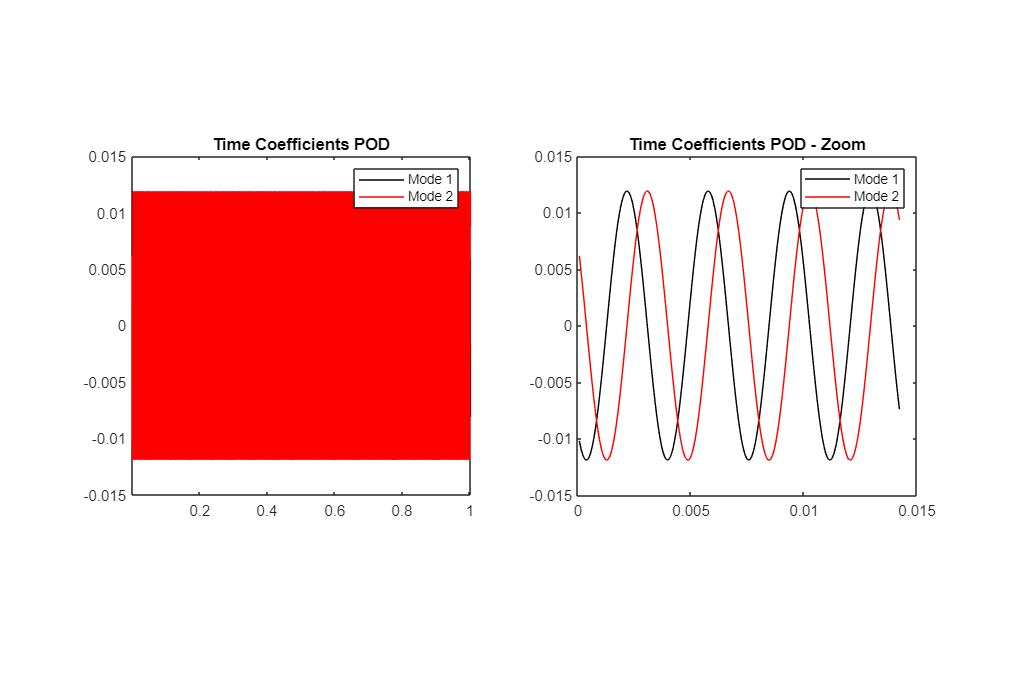

TimeCoefficients1=V_POD(:,1); %1st mode
TimeCoefficients_m=V_POD(:,m); %m-th mode

% Plot
figure('Renderer','painters','Position',[10 10 900 600])
subplot(1,2,1);
plot(t,TimeCoefficients1,'k-'); hold on; axis equal; axis square;
plot(t,TimeCoefficients_m,'r-');
xlim([t(1) t(end)]);
title('Time Coefficients POD');
legend('Mode 1',['Mode ' num2str(m,'%0.0f')]);

% Zoom
subplot(1,2,2);
plot(t(1:200),TimeCoefficients1(1:200),'k-'); hold on; axis equal; axis square;
plot(t(1:200),TimeCoefficients_m(1:200),'r-');
title('Time Coefficients POD - Zoom');
legend('Mode 1',['Mode ' num2str(m,'%0.0f')]);

Note the V matrix for modes 1 and 2 is also a pair of sine waves; confirming the traveling wave behavior of the modes. 

## Frequency-time analysis

% Computing the mode expansion coefficients of the first nModes modes
% using a windowing function consistent with the SPOD.

nFFT=1024; % To change coherently with the number of snapshots
window=hann(nFFT);
% Number of modes.
nModes=2;

% Expansion coefficient function tcoeffs.
a=tcoeffs(field_Snapshots,P,hann(nFFT),[],nModes);

 
Calculating expansion coefficients. It might take a while...
------------------------------------------------------------


## Visualize the results. Frequency-time plot (dynamic spectrum).

% Plot
figure('Renderer','painters','Position',[10 10 900 600])
% First mode
pcolor(t*V_inf/c,f*c/V_inf,abs(squeeze(a(:,:,1)))); shading interp; colorbar;
title(strcat(['First mode frequency-time diagram,' ...
    ' '], num2str(sum(L(:,1))/sum(L(:))*100),'%3.1f'), '% of energy)');
xlab=xlabel("$t \frac{V_{\infty}{c}$"); 
ylab=ylabel("$St$"); caxis([-0.75 0.75].*caxis);
set(xlab,'Interpreter', 'latex','FontSize',20); 
set(ylab,'Interpreter','latex','Rotation',0,'FontSize',20); 
set(gca,'FontSize',11); 

% nModes modes (sum of the first nModes modes)
% subplot(2,1,2)
% pcolor(t,f,squeeze(abs(sum(a,nModes)))); shading interp; colorbar
% %daspect([100 1 1])
% title(['frequency-time diagram (sum of first ' num2str(nModes) ' modes, ' ...
%     '' num2str(sum(sum(L(:,1:nModes)))/sum(L(:))*100,'%3.1f') '% of energy)'])
% xlabel('time'), ylabel('frequency'), caxis([0 0.75].*caxis)


## Bibliography

[1] Schioppa, A., “On the Onset of Buffet and Drag Divergence in ultra-low-Reynolds Number Compressible Flows”, Report, ISAE-SUPAERO, 2022.